# Weak Imposition of Dirichlet Boundary Conditions for the Timoshenko Beam Boundary Value Problem

## Introduction

This chapter discusses the application of the weak Dirichlet boundary conditions for the one-dimensional Timoshenko beam problem using both the Penalty and the Lagrange Multipliers methods. The *Boundary Value Problem* (BVP) associated with the Timoshenko beam problem is detailed in the [introduction of Chapter 2](matlab:open('..\2_TimoshenkoBeam\main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')).

The standard weak formulation of the Timoshenko beam boundary value problem imposes strongly both subsidiary conditions regarding the constitutive equations and the kinematics in the principle of virtual work, namely,


$$\int_0^L \overbrace{\delta \left( \frac{\text{d} w}{\text{d} x} + \beta \right) \alpha G A \left( \frac{\text{d} w}{\text{d} x} + \beta \right)}^{\text{shear part of the stiffness}} + \overbrace{\delta \frac{\text{d} \beta}{\text{d} x} \, E I \, \frac{\text{d} \beta}{\text{d} x}}^{\text{bendingpart of the stiffness}} \; \text{d} x = \overbrace{\int_0^L \overline{q} \, \delta w + \overline{m} \, \delta \beta \; \text{d}x }^{\text{source loads}} + \overbrace{\left[ \delta w \, Q \right]_0^L + \left[ \delta \beta \, M \right]_0^L}^{\text{boundary loads}} \;. \qquad (1)$$


The boundary terms in Eq. (4) can be expanded as follows:


$$\left[ \delta w \, Q \right]_0^L + \left[ \delta \beta \, M \right]_0^L = \delta w \left( x = L \right) Q \left( x = L \right) - \delta w \left( x = 0 \right) Q \left( x = 0 \right) + \delta \beta \left( x = L \right) M \left( x = L \right) - \delta \beta \left( x = 0 \right) Q \left( x = 0 \right) = \delta w_L Q_l + \delta w_0 Q_0 + \delta \beta_L M_l + \delta \beta_0 M_0$$


If we assume that the variations $\delta w, \delta \beta$ does not vanish on the Dirichlet boundary $\Gamma_d \subset \{ 0,L \}$, then the latter terms associated with the Dirichlet boundary cannot be eliminated from the system. To impose the Dirichlet boundary conditions


$$\begin{array}{l}
w=\bar{w} ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 1\right)\\
\beta =\bar{\beta} ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(2\ldotp 2\right)
\end{array}$$


extended variational formulations need to be employed:

1.) The **Penalty** method: One assumes the following equalities one the Dirichlet boundary $\Gamma_d$:


$$\begin{array}{l}
Q=\alpha_w \;\left(w-\bar{w} \right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 1\right)\\
M=\alpha_{\beta } \;\left(\beta -\bar{\beta} \right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 2\right)
\end{array}$$


In this way, the boundary terms $\delta w \, Q + \delta \beta \, M$become:


$$\begin{array}{l}
\delta w\;Q\;=\delta w\;\alpha_w \;\left(w-\bar{w} \right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 1\right)\\
\delta \beta \;M=\delta \beta \;\alpha_{\beta } \;\;\left(\beta -\bar{\beta} \right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 2\right)
\end{array}$$


where $\alpha_w \;$and $\alpha_{\beta }$ are Penalty parameters that need to be manually set. The larger the Penalty parameter the better the corresponding boundary condition is fulfilled. However, the condition number of the resulting linear equation system degrades quickly as the magnitude of the Penalty parameter is increased resulting into inaccurate results or even singular equation systems.

2.) The **Lagrange Multipliers** method: One assumes the following equalities one the Dirichlet boundary $\Gamma_d$:


$$\begin{array}{l}
Q=\lambda \;\left(w-\bar{w} \right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\ldotp 1\right)\\
M=\mu \;\left(\beta -\bar{\beta} \right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\ldotp 2\right)
\end{array}$$


where $\lambda$ and $\mu$ are unknown distributions along the Dirichlet boundary $\Gamma_d$ that are sought. These two additional fields act as Lagrange Multipliers for the imposition of the Dirichlet boundary conditions. If the extended variational form of the problem using the Lagrange Multipliers method is denoted by $\delta W_{\text{int, ext}} = \frac{\partial W_{\text{int, ext}}}{\partial w} \delta w + \frac{\partial W_{\text{int, ext}}}{\partial \beta} \delta \beta + \frac{\partial W_{\text{int, ext}}}{\partial \lambda} \delta \lambda + \frac{\partial W_{\text{int, ext}}}{\partial \mu} \delta \mu$. Collecting the DOFs of the pair of primal unknown fields $\left( w, \beta \right)$ into a vector $\mathbf{u}$ and the pair of Lagrange Multipliers $\left( \lambda, \mu \right)$ into a vector $\mathbf{\beta}$, the resulting linear equation system after the discretization writes,

$\left[ \begin{array}{cc} \mathbf{K} & \mathbf{\Lambda} \\ \mathbf{\Lambda}^{\text{T}} & \mathbf{0} \end{array} \right] \left[ \begin{array}{c} \mathbf{u} \\ \mathbf{\beta} \end{array} \right] = \left[ \begin{array}{c} \mathbf{F} + \overline{\mathbf{F}} \\ \mathbf{0} \end{array} \right]$                       (6)

where,

$\mathbf{\Lambda} =\int_{\Gamma_d} \mathbf{N}_u^{\text{T}} \mathbf{N}_\lambda \; \text{d} \Gamma$                                 (7)

$\mathbf{N}_u$ being the matrix of the basis functions for the discretization of the primal unknown fields $\left( w, \beta \right)$ and $\mathbf{N}_\lambda$ the matrix of the basis functions for the discretization of the secondary unknown fields $\left( \lambda, \mu \right)$. Lastly, $\overline{\mathbf{F}} $ stands for the effective load vector that results from the inhomogeneous part of the Dirichlet boundary conditions:

$\overline{\mathbf{F}}  = \int_{\Gamma_d } \delta w \, \overline{w} + \delta \beta \, \overline{\beta} \; \text{d} \Gamma$                       (8)

It is clear that the pair of Lagrange Multipliers $\left( \lambda, \mu \right)$ represents the reaction tranverse shear forces and reaction bending moments along the Dirichlet boundary. This type of problems are called mixed Finite Element formulations and result in saddle-point problems whose unique solution cannot be in general guaranteed unless the so-called inf-sup (or LBB) condition is satisfied.

The example setup used herein for demonstration is the same one as in Chapter 1, see [here](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')). This setup is a cantilever beam subject to vertical distributed load, see the following figure accordingly:

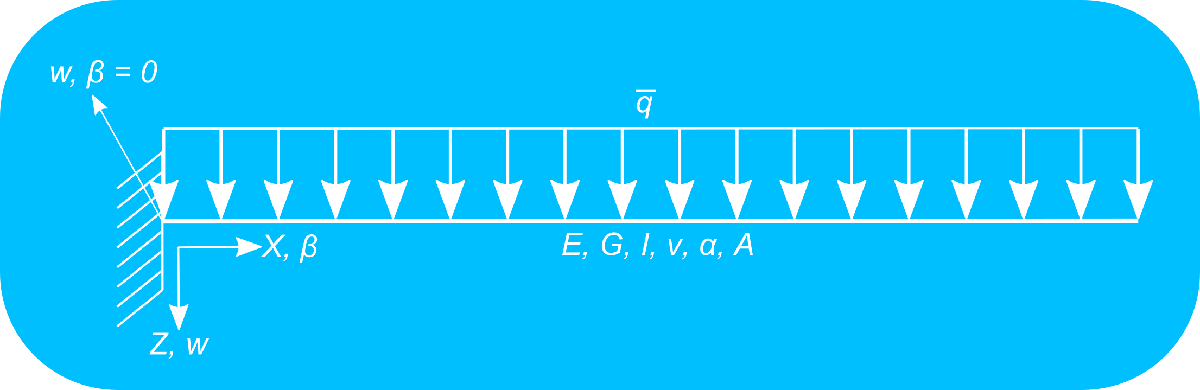

As a reference solution it herein used the solution derived in script [`main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx`](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')) and highlighted [here](matlab:open('..\1_TimoshenkoBeam\main_Chapter1_ALinearStraightTimoshenkoBeamElement.mlx')), since both setups are equivalent.

The error of the Finite Element discretization is then computed by means of the $L^2(0,L)$-norm in the domain, namely,


$$\left\| w - w_h \right\|_{L^2(0,L)} = \left( \int_0^L \left( w - w_h \right)^2 \; \text{d} x \right)^{1/2} \qquad (9.1)\\
\left\| \beta - \beta_h \right\|_{L^2(0,L)} = \left( \int_0^L \left( \beta - \beta_h \right)^2 \; \text{d} x \right)^{1/2} \qquad \; \, (9.2)$$


[PREVIOUS Chapter](matlab:open('..\4_TransverseShearLocking\4_TransverseShearLocking_ReissnerMindlinSquarePlate\main_Chapter4_Locking_ReissnerMindlinSquarePlate.mlx')) *Transverse-Shear Locking in Shear-Deformable Plates *`-`* Two Sided Clampled Plate Subject to Vertical Distributed Load*

[NEXT Chapter](matlab:open('..\6_HellingerReissnerFormulation\main_Chapter6_HellingerReissnerFormulation_TimoshenkoBeam.mlx')) *Hellinger-Reissner Formulation for the Timoshenko Beam Boundary Value Problem*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Definition of the problem parameters**

### Definition of geometric parameters

Thickness [m]

propStr.t = 10^(-2);

Width [m]

propStr.b = .1;

Height [m^2]

propStr.A = propStr.b*propStr.t;

X-coordinate at the left end of the beam [m]

X0 = 0;

Y-coordinate at the right end of the beam [m]

XL = 4;

### Definition of material paramerters

Distributed load along the beam's length [N/m^2]

propStr.qBar = -1e4*(propStr.t)^3;

Distributed moment along the beam's length [N/m]

propStr.mBar = 0;

Boundary force [N]

propStr.Q = 0;

Boundary moment [Nm]

propStr.M = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0;

Moment of inertia [m^4]

propStr.I = propStr.b*(propStr.t^3)/12;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/(2*(1 + propStr.nu));

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Analytical solution

Initialization of the individual constituents

syms wEx(X) betaEx(X) Q(X) Lsym qsym Gsym Aqsym Esym Isym

Set the analytical solution in terms of the vertical deflection field

wEx(X) = (qsym*Lsym*X-qsym*X^2/2)/Gsym/(Aqsym) - ...
    (-qsym*X^4/24+qsym*Lsym*X^3/6-qsym*Lsym^2*X^2/4)/Esym/Isym;

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{Q} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x$$


betaEx(X) = int(-1/(propStr.alpha*propStr.G*propStr.A)*propStr.qBar ...
    - diff(diff(wEx, X), X));

Evaluation of the expressions for the given geometric and material parameters

wEx(X) = subs(wEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, propStr.alpha*propStr.b*propStr.t})

$$wEx(X) = -\frac{36893488147419103232\,X^{4}}{7378697629483822265625}+\frac{590295810358705651712\,X^{3}}{7378697629483822265625}-\frac{37778837415627504316643\,X^{2}}{78706108047827437500000}-\frac{3\,X}{312500}$$

betaEx(X) = subs(betaEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, propStr.alpha*propStr.b*propStr.t})

$$betaEx(X) = \frac{147573952589676412928\,X^{3}}{7378697629483822265625}-\frac{590295810358705651712\,X^{2}}{2459565876494607421875}+\frac{5575186299632655785385758414771132913963829\,X}{5807485728784017717537238004269056000000000}$$

## Choose shape functions for the primal field interpolation $\left( w, \beta \right)$

  **Try**

Change the value of parameter `choiceShapeFunctionsPrimal` from the dropdown list to get either a linear two-noded or a quadratic three-noded Finite Element mesh

choiceShapeFunctionsPrimal = 1;
syms Nu(xi)
switch choiceShapeFunctionsPrimal

### Linear (hat) shape functions


$$\begin{array}{l}
N_1 \left(\xi \right)=\frac{1-\xi }{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(10\ldotp 1\right)\\
N_2 \left(\xi \right)=\frac{1+\xi }{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(10\ldotp 2\right)
\end{array}$$


    case 1
        Nu(xi) = [1/2*(1 - xi) 1/2*(1 + xi)];

### Quadratic shape functions


$$\begin{array}{l}
N_1 \left(\xi \right)=\frac{\xi \;\left(\xi -1\right)}{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(11\ldotp 1\right)\\
N_2 \left(\xi \right)=\frac{\xi \;\left(\xi +1\right)}{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(11\ldotp 2\right)\\
N_3 \left(\xi \right)=-\left(\xi -1\right)\;\;\left(\xi +1\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(11\ldotp 3\right)
\end{array}$$


    case 2
        Nu(xi) = [(xi*(xi - 1))/2 -(xi - 1)*(xi + 1) (xi*(xi + 1))/2];

    otherwise
        error("Only linear two-noded and quadratic three-noded elements are supported")
end

## Discretization

Both vertical deflection and rotation fields are discretized using the linear (hat) basis (shape) functions, namely:


$$\begin{array}{l}
w\left(x\right)\approx \sum_{i=1:N} N_i^w \;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 1\right)\\
\beta \left(x\right)\approx \sum_{i=1:N} N_i^{\beta } \;\beta_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 2\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### One-dimensional mesh using linear two-noded elements

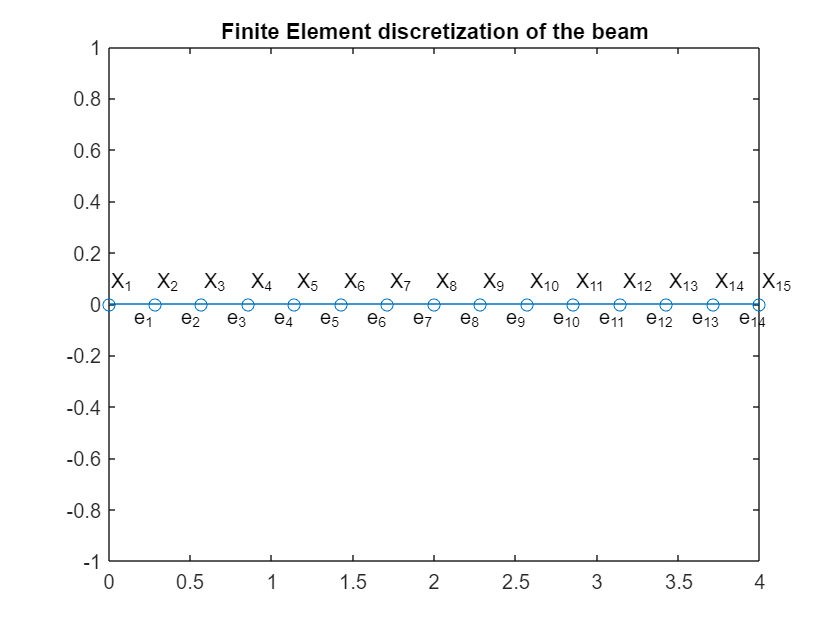

numEl = 14;
msh = generateLinearMeshOnLine(X0, XL, numEl);
if choiceShapeFunctionsPrimal == 2
    msh = generateQuadraticMeshOnLine(msh);
end
numNodesU = numel(msh.nodes(:, 1));
plotMesh1d(msh);
title("Finite Element discretization of the beam")

### Dirichlet boundary conditions by means of the node numbering

numDOFs = 2*numNodesU;
freeDOFs = 1:numDOFs;
homDOFs = 1:2;
[~, idx] = ismember(homDOFs, freeDOFs);
freeDOFs(idx) = [];

## Master stiffness matrix corresponding to the Timoshenko beam element

### Compute the master stiffness matrix and load vector

switch choiceShapeFunctionsPrimal
    case 1
        computeBasisFunctionsAndDerivsU = ...
            @computeLinearBasisFunctionsAndFirstDerivatives;
    case 2
        computeBasisFunctionsAndDerivsU = ...
            @computeQuadraticBasisFunctionsAndFirstDerivatives;
end
computeStiffMatrixandForceVector = 'undefined';
computeBasisFunctionsAndDerivs_beta = 'undefined';
[K, FBody] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeamRIPageWise ...
    (msh, computeStiffMatrixandForceVector, ...
    computeBasisFunctionsAndDerivsU, ...
    computeBasisFunctionsAndDerivs_beta, propStr);

Visualization of the sparsity of the master stiffness matrix using linear two-noded finite elements

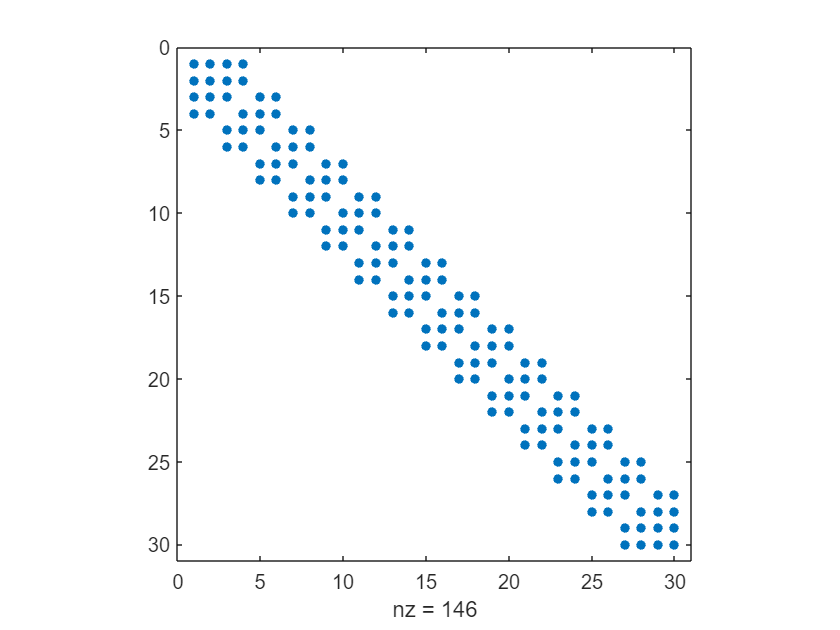

spy(K)

### **Nodal force vector corresponding to boundary forces**

FBoundary = zeros(2*numNodesU, 1);
FBoundary(end - 1, 1) = propStr.Q;
FBoundary(end, 1) = propStr.M;

#### Summation of the body-force vector corresponding to distributed loads with the body-force vector corresponding to boundary loads

F = FBody + FBoundary;

## Imposition of weak Dirichlet boundary conditions using the Penalty method

### Penalty parameters

The variables `expU` and `expBeta` below stand for the exponents of the corresponding Penalty parameters, namely, $\alpha_w= \exp(\text{expU})$ and $\alpha_\beta= \exp(\text{expBeta})$, for the Dirichlet conditions of the vertical displacements and cross-sectional rotations, respectively.

  **Try**

Change the value of variables `expU` and `expBeta` using the numeric sliders below, observe how the error on the Dirichlet boundary $\left\| w \right\|_{L^2\left(  \Gamma_{\text{d} }\right)} + \left\| \beta \right\|_{L^2\left(  \Gamma_{\text{d} }\right)} = w(X=0) + \beta(X=0)$, the error in the domain $\left\| w - w_h \right\|_{L^2\left(  0, L \right)}$, $\left\| \omega - \omega_h \right\|_{L^2\left(  0, L \right)}$, and the deformation varies for the different values of the Penalty parameters

expU = 2;
expBeta = 1;
alphaU = 10^expU;
alphaBeta = 10^expBeta;

### Stiffness matrix accounting for the Penalty contributions and solution of the linear equation system

Kpenalty = ...
    utilityFunctionsWeakDBCTimoshenkoBeam.computePenaltyMtxWeakDirichletBoundaryConditions ...
    (msh, alphaU, alphaBeta, homDOFs, computeBasisFunctionsAndDerivsU);
stiffMtx_Penalty = K + Kpenalty;
uPenalty = stiffMtx_Penalty\F;

### Error on the Dirichlet boundary

disp("Error in the vertical deflection at the " + ...
    "Dirichlet boundary (Penalty): " + sum(abs(uPenalty(homDOFs))));

Error in the vertical deflection at the Dirichlet boundary (Penalty): 0.0084


### Error in the domain L2-norm 

numGP = 4;
[errL2PenaltyU, errL2PenaltyBeta] = ...
    computeL2ErrorTimoshenkoBeam ...
    (msh, uPenalty, computeBasisFunctionsAndDerivsU, wEx, betaEx, numGP);
disp("Error in the L2-norm for the vertical deflection " + ...
    "in the domain (Penalty): " + errL2PenaltyU);

Error in the L2-norm for the vertical deflection in the domain (Penalty): 0.036182


disp("Error in the L2-norm for the cross-sectional rotation " + ...
    "in the domain (Penalty): " + errL2PenaltyBeta);

Error in the L2-norm for the cross-sectional rotation in the domain (Penalty): 0.016523


### Visualization of the deformed configuration

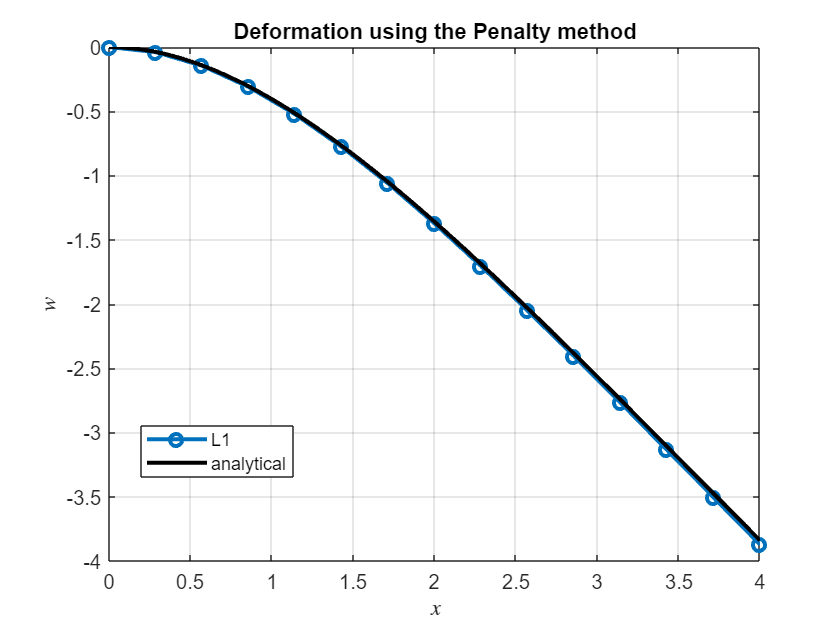

plot_postprocConfigurationTimoshenkoBeam ...
    (msh, uPenalty, "displacement", choiceShapeFunctionsPrimal);
hold on;
fplot(wEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
if choiceShapeFunctionsPrimal == 1
    str = "1";
else
    str = "2";
end
legend("L" + str, "analytical", Location="best")
title("Deformation using the Penalty method")

### Visualization of the cross-sectional rotation field

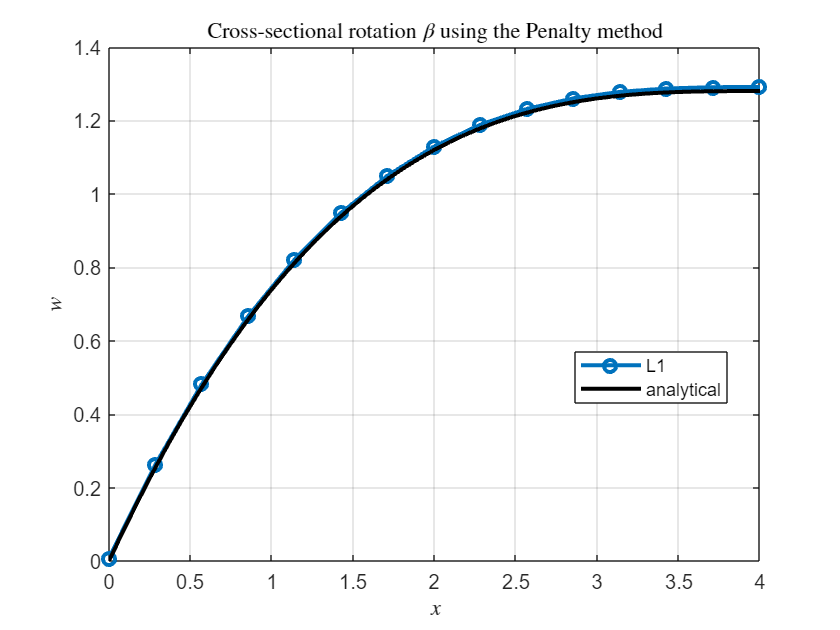

plot_postprocConfigurationTimoshenkoBeam ...
    (msh, uPenalty, "rotation", choiceShapeFunctionsPrimal);
hold on;
fplot(betaEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
if choiceShapeFunctionsPrimal == 1
    str = "1";
else
    str = "2";
end
legend("L" + str, "analytical", Location="best")
title("Cross-sectional rotation $\beta$ using the Penalty method", ...
    Interpreter="latex")

###   **Try**

Change the values for the exponents of the Penalty parameters and observe the solution in the figure below.

 **Reflect**

How do the errors vary as the Penalty parameters are changed?

  **Try**

Visualize the sparsity pattern of the stiffness matrix with the Penalty contributions.

 **Reflect**

Why are there non-zero entries outside the main diagonal? What do these entries represent?

## Imposition of weak Dirichlet boundary conditions using the Lagrange Multipliers method

Lambda = ...
    utilityFunctionsWeakDBCTimoshenkoBeam.computeLagrangeMultipliersMtxWeakDirichletBoundaryConditions ...
    (msh, homDOFs, computeBasisFunctionsAndDerivsU);

### Computation of the stiffness matrix accounting for the Lagrange Multipliers contributions and solution of the linear equation system

numDOFsLM = numel(homDOFs);
stiffMtxLM = [K                 Lambda
              transpose(Lambda) zeros(numDOFsLM)];
loadVctLM = [F
              zeros(numDOFsLM, 1)];
uLM = stiffMtxLM\loadVctLM;

### Visualization of the deformed configuration

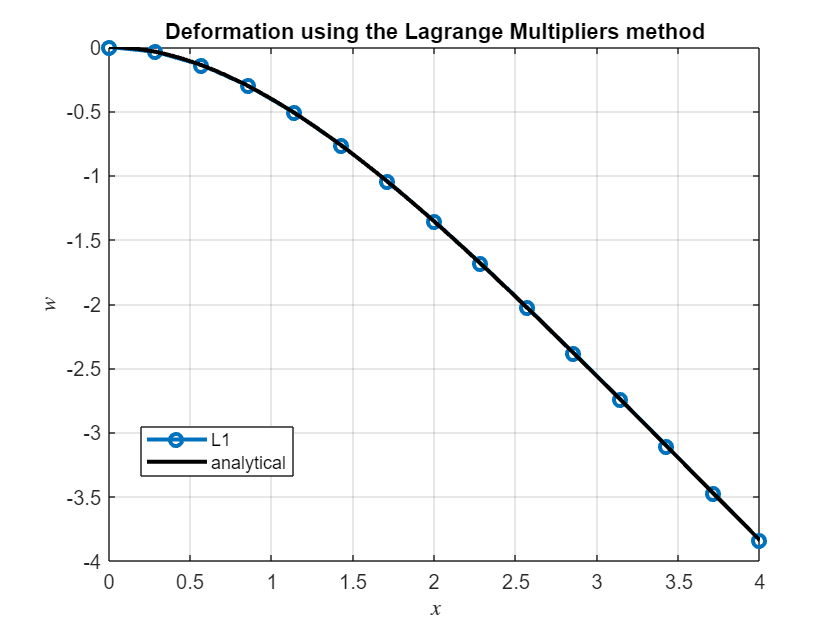

plot_postprocConfigurationTimoshenkoBeam ...
    (msh, uLM, "displacement", choiceShapeFunctionsPrimal);
hold on;
fplot(wEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
if choiceShapeFunctionsPrimal == 1
    str = "1";
else
    str = "2";
end
legend("L" + str, "analytical", Location="best")
title("Deformation using the Lagrange Multipliers method")

### Visualization of the cross-sectional rotation field

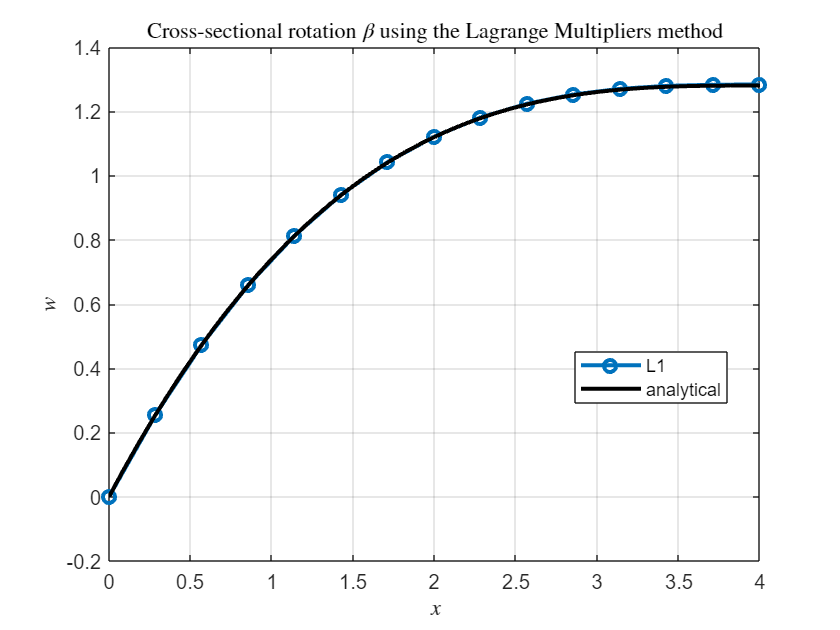

plot_postprocConfigurationTimoshenkoBeam ...
    (msh, uLM, "rotation", choiceShapeFunctionsPrimal);
hold on;
fplot(betaEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
if choiceShapeFunctionsPrimal == 1
    str = "1";
else
    str = "2";
end
legend("L" + str, "analytical", Location="best")
title("Cross-sectional rotation $\beta$ using " + ...
    "the Lagrange Multipliers method", Interpreter="latex")

### Computation of the error on the Dirichlet boundary

disp("Error in the vertical deflection at the Dirichlet " + ...
    "boundary (Lagrange Multipliers): " + sum(abs(uLM(homDOFs))));

Error in the vertical deflection at the Dirichlet boundary (Lagrange Multipliers): 2.8948e-25


### Computation of the error in the $L^2(0,L)$-norm

numGP = 4;
[errL2LMU, errL2LMBeta] = computeL2ErrorTimoshenkoBeam ...
    (msh, uLM(1:numDOFs), computeBasisFunctionsAndDerivsU, ...
    wEx, betaEx, numGP);
disp("Error in the L2-norm for the vertical deflection " + ...
    "in the domain (Lagrange Multipliers): " + errL2LMU);

Error in the L2-norm for the vertical deflection in the domain (Lagrange Multipliers): 0.0054201


disp("Error in the L2-norm for the cross-sectional rotation " + ...
    "in the domain (Lagrange Multipliers): " + errL2LMBeta);

Error in the L2-norm for the cross-sectional rotation in the domain (Lagrange Multipliers): 0.0041243


  **Try**

Visualize the sparsity pattern of the stiffness matrix with the Lagrange Multipliers contributions.

 **Reflect**

Why are there non-zero entries outside the main diagonal? What do these entries represent?

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

[[2] Apostolatos, Andreas, et al. "A Nitsche‐type formulation and comparison of the most common domain decomposition methods in isogeometric analysis." *International Journal for Numerical Methods in Engineering* 97.7 (2014): 473-504.](https://doi.org/10.1002/nme.4568)